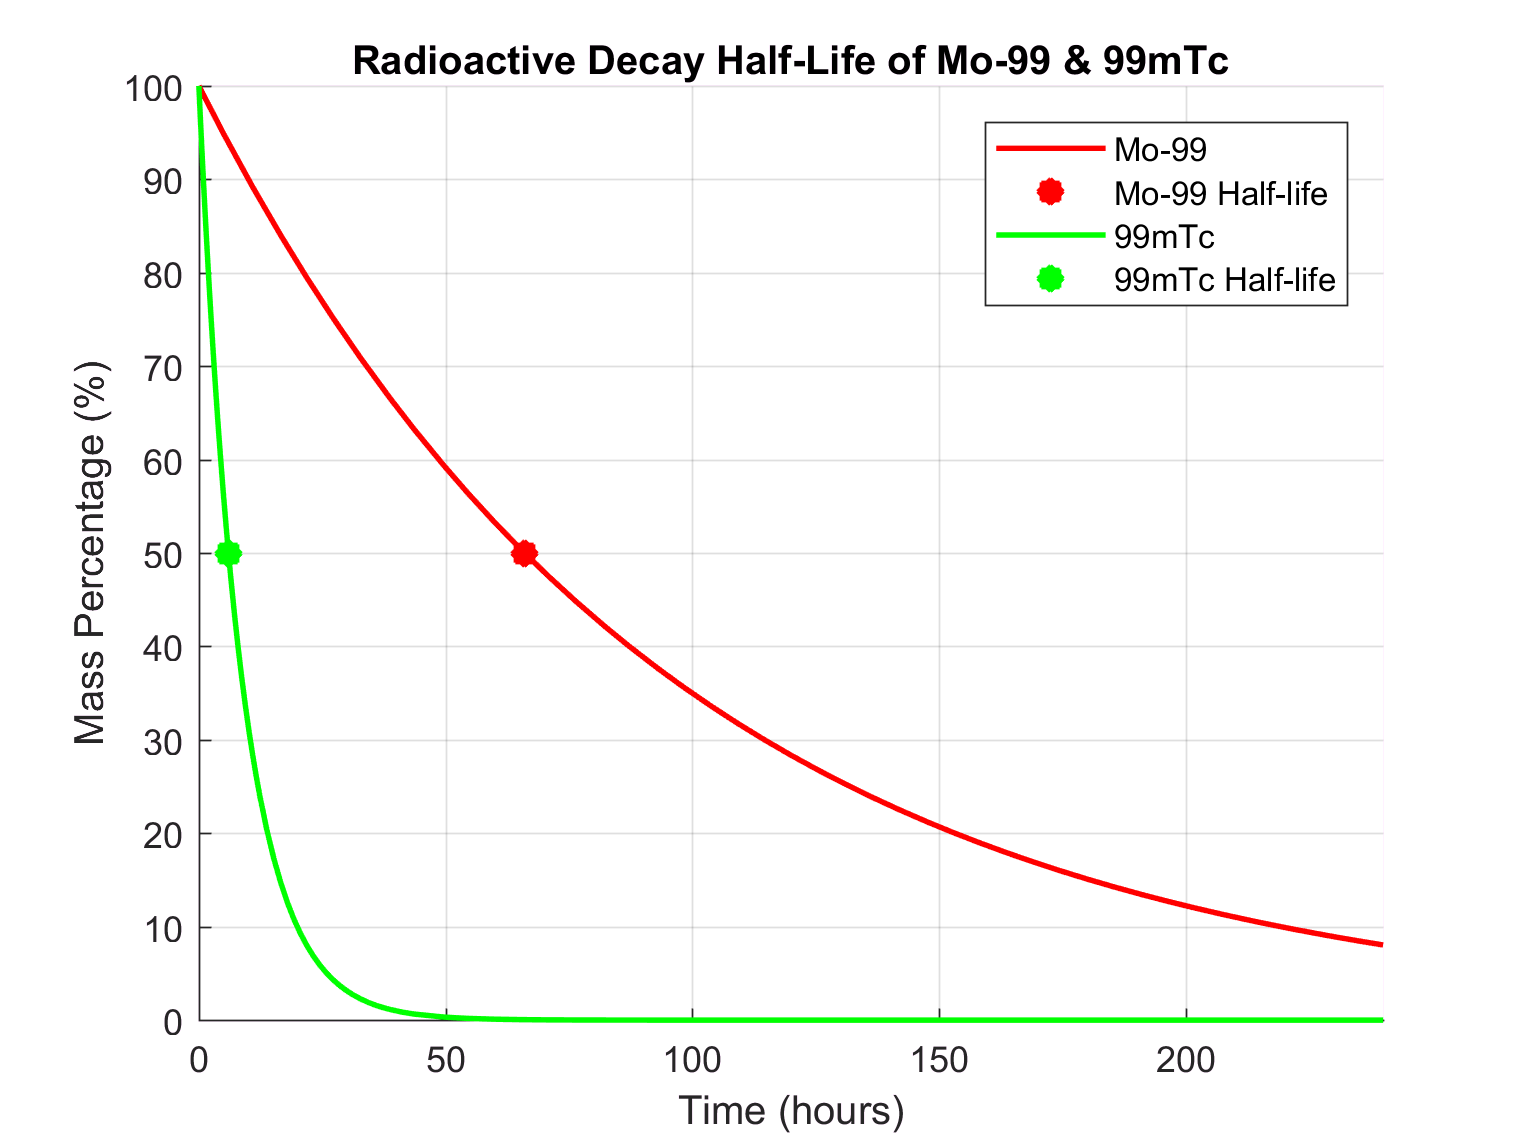

close all; clear all;
syms t T;
A = 100; %Kg

% Mo-99 (66-hour decay rate)
halfLifeM = 66; %hours
kM = (log(2)/halfLifeM);
yM(t) = A*exp(-kM*t);

% 99mTc (66-hour decay rate)
halfLifeT = 6; %hours
kT = (log(2)/halfLifeT);
yT(t) = A*exp(-kT*t);

% plot
hold on;
fplot(yM(t), [0, 240], '-r', 'LineWidth', 1.5);
plot(66, 50, '*r', 'LineWidth', 5);
fplot(yT(t), [0, 240], '-g', 'LineWidth', 1.5);
plot(6, 50, '*g', 'LineWidth', 5);
grid on;
ylim([0 100]);
title('Radioactive Decay Half-Life of Mo-99 & 99mTc');
xlabel('Time (hours)');
ylabel('Mass Percentage (%)');
legend('Mo-99', 'Mo-99 Half-life', '99mTc', '99mTc Half-life');